Now reading 286(78).tif


Now reading 286(79).tif


Now reading 286(80).tif


Now reading 286(81).tif


Now reading 286(82).tif


Now reading 286(83).tif


Now reading 286(84).tif


Now reading 286(85).tif


Now reading 286(86).tif


Now reading 286(87).tif


Now reading 286(88).tif


Now reading 286(89).tif


Now reading 286(90).tif


Now reading 286(91).tif


Now reading 286(92).tif


Now reading 286(93).tif


Now reading 286(94).tif


Now reading 286(95).tif


Now reading 286(96).tif


Now reading 286(97).tif


Now reading 286(98).tif


Now reading 286(99).tif


Now reading 286(100).tif


Now reading 286(101).tif


Now reading 286(102).tif


Now reading 286(103).tif


Now reading 286(104).tif


Now reading 286(105).tif


Now reading 286(106).tif


Now reading 286(107).tif


Now reading 286(108).tif


Now reading 286(109).tif


Now reading 286(110).tif


Now reading 286(111).tif


Now reading 286(112).tif


Now reading 286(113).tif


Now reading 286(114).tif


Now reading 286(115).tif


Now reading 286(116).tif


Now reading 286(117).tif


Now reading 286(118).tif


Now reading 286(119).tif


Now reading 286(120).tif


Now reading 286(121).tif


Now reading 286(122).tif


Now reading 286(123).tif


Now reading 286(124).tif


Now reading 286(125).tif


Now reading 286(126).tif


Now reading 286(127).tif


Now reading 286(128).tif


Now reading 286(129).tif


Now reading 286(130).tif


Now reading 286(131).tif


Now reading 286(132).tif


Now reading 286(133).tif


Now reading 286(134).tif


Now reading 286(135).tif


Now reading 286(136).tif


Now reading 286(137).tif


Now reading 286(138).tif


Now reading 286(139).tif


Now reading 286(140).tif


Now reading 286(141).tif


Now reading 286(142).tif


Now reading 286(143).tif


Now reading 286(144).tif


Now reading 286(145).tif


Now reading 286(146).tif


Now reading 286(147).tif


Now reading 286(148).tif


Now reading 286(149).tif


Now reading 286(150).tif


Now reading 286(151).tif


Now reading 286(152).tif


Now reading 286(153).tif


Now reading 286(154).tif


Now reading 286(155).tif


Now reading 286(156).tif


Now reading 286(157).tif


Now reading 286(158).tif


Now reading 286(159).tif


Now reading 286(160).tif


Now reading 286(161).tif


Now reading 286(162).tif


Now reading 286(163).tif


Now reading 286(164).tif


Now reading 286(165).tif


Now reading 286(166).tif


Now reading 286(167).tif


Now reading 286(168).tif


Now reading 286(169).tif


Now reading 286(170).tif


Now reading 286(171).tif


Now reading 286(172).tif


Now reading 286(173).tif


Now reading 286(174).tif


Now reading 286(175).tif


Now reading 286(176).tif


Now reading 286(177).tif


Now reading 286(178).tif


Now reading 286(179).tif


Now reading 286(180).tif


Now reading 286(181).tif


Now reading 286(182).tif


Now reading 286(183).tif


Now reading 286(184).tif


Now reading 286(185).tif


Now reading 286(186).tif


Now reading 286(187).tif


Now reading 286(188).tif


Now reading 286(189).tif


Now reading 286(190).tif


Now reading 286(191).tif


Now reading 286(192).tif


Now reading 286(193).tif


Now reading 286(194).tif


Now reading 286(195).tif


Now reading 286(196).tif


Now reading 286(197).tif


Now reading 286(198).tif


Now reading 286(199).tif


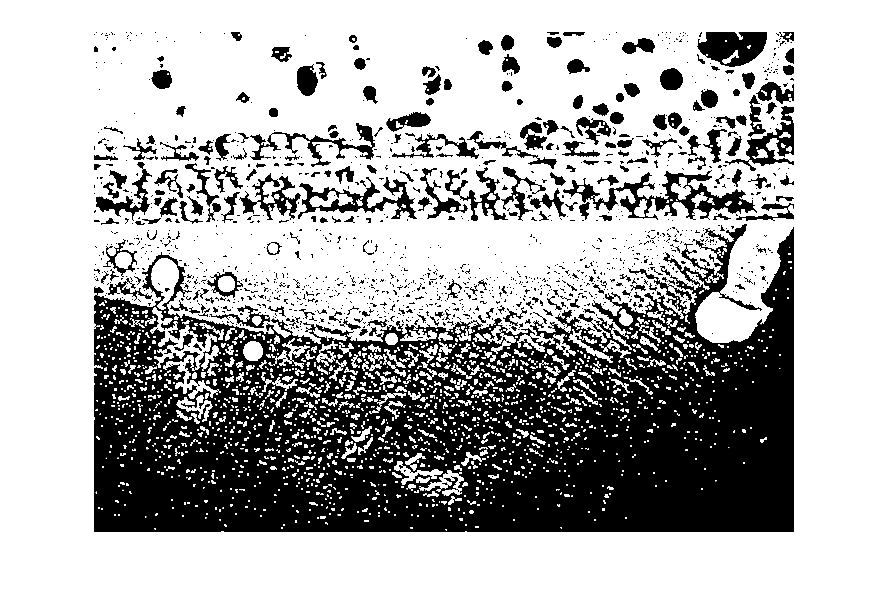

% Filter designed for Keyhole Segmentation Tool
% by William Dong and Jason Lian @ UW-Madison
% The image file need to be named as "DatasetIndex(ImgIndex)"

DatasetIndex = 286;
imgFolder = "YourDirectory"+num2str(DatasetIndex);
storingPath = "YourDirectory"+num2str(DatasetIndex);

%check if exist
if ~isfolder(imgFolder)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', imgFolder);
  uiwait(warndlg(errorMessage));
  return;
end

filePattern = fullfile(imgFolder, '*.tif');
tifImgs = dir(filePattern);
tifImgs = natsortfiles(tifImgs);

%loop for filtering images
for k = 78:199
    ImgIndex = k;
    baseImgName = tifImgs(ImgIndex).name;
    fullImgName = fullfile(imgFolder, baseImgName);
    fprintf('Now reading %s\n', baseImgName);
    imageJ = imread(fullImgName);

    ImgSize = size(imageJ);
    ImgTotal = uint16(zeros(ImgSize));
    
    %loop for extracting previous 40 images
    for TotalIndex=1:40
        TotalDir = imgFolder+"\"+num2str(DatasetIndex)+"("+num2str(TotalIndex)+").tif";
        ImgStream = imread(TotalDir);
        ImgTotal = ImgTotal + ImgStream/40;
    end
    
    %Filter and resize the Image
    MeanDiff = mean(mean(ImgTotal))-mean(mean(imageJ));
    imageJ = imageJ + MeanDiff;
    ImgDiff = imageJ-ImgTotal;
    imgDiff = imbinarize(ImgDiff,0);
    ImgDiff = ImgDiff * 255;

    imshow(ImgDiff);
    
    K = imresize(ImgDiff,[500 700]);

    %binary to rgb to save as PNG
    image3D(:,:,1) = K;
    image3D(:,:,2) = K;
    image3D(:,:,3) = K;
    image3D = uint8(image3D);

    imshow(image3D);

    %save the image
    imwrite(image3D, fullfile(storingPath, num2str(DatasetIndex) + "(" + num2str(ImgIndex)+ ").png"), "png");
end